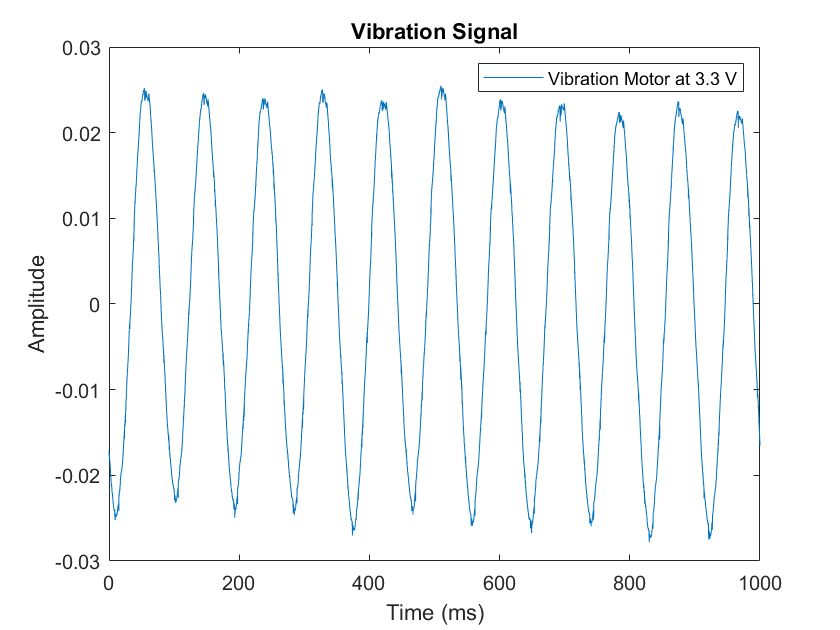

% Extract time region of interest from signals

% Generated by MATLAB(R) 9.9 and Signal Processing Toolbox 8.5.
% Generated on: 25-Jul-2021 17:53:43

% Parameters
timeLimits = [0 0.1]; % seconds
t = linspace(0,1000, 10001);

%%
sampleRate = 100000; % Hz
startTime = 0; % seconds
minIdx = ceil(max((timeLimits(1)-startTime)*sampleRate,0))+1;
maxIdx = floor(min((timeLimits(2)-startTime)*sampleRate,length(empty_bottle_1_ROI)-1))+1;
empty_bottle_1_ROI = detrend(empty_bottle_1_ROI(minIdx:maxIdx));
plot(t,empty_bottle_1_ROI);
xlabel('Time (ms)');
ylabel('Amplitude');
legend('Vibration Motor at 3.3 V')
title('Vibration Signal')

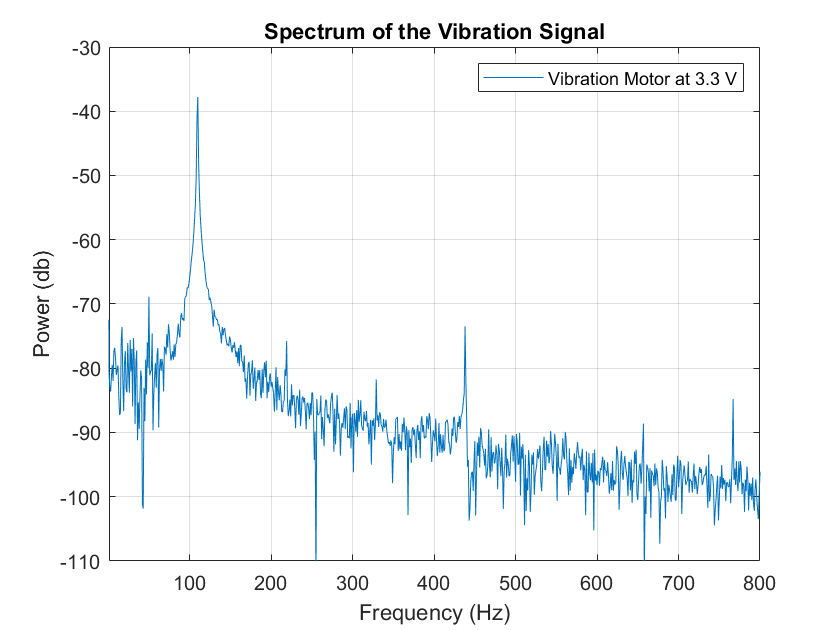


Fs = 100000;          % Sampling frequency (100 kHz)                   
T = 1/Fs;             % Sampling period       
NFFT = length(empty_bottle_1); %empty.mat
[P,F] = periodogram(empty_bottle_1,[],NFFT,Fs,'power');
plot (F,10*log10(P));
grid on
legend('Vibration Motor at 3.3 V')
title('Spectrum of the Vibration Signal')
xlim([1 800])
ylim([-110 -30])
xlabel('Frequency (Hz)')
ylabel ('Power (db)')

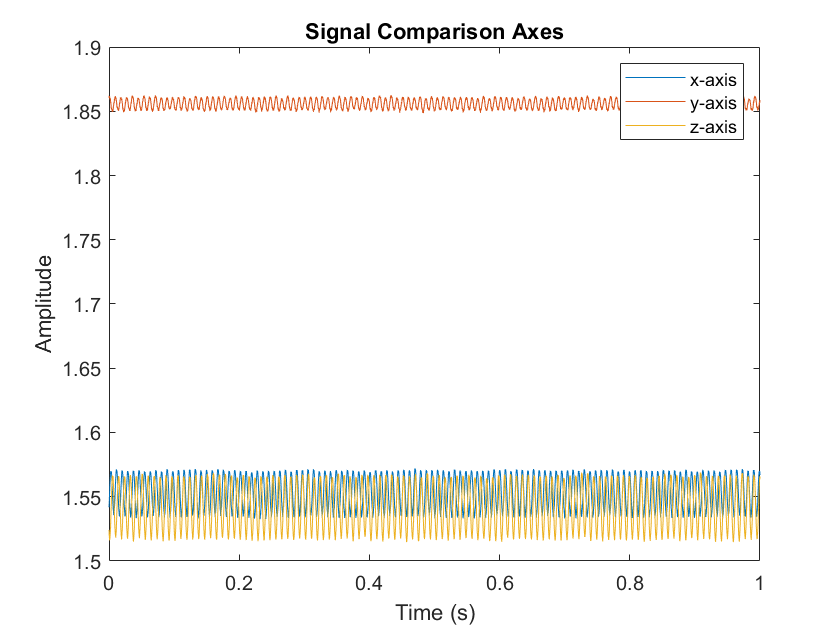


%%comparison axes
% Extract time region of interest from signals

% Generated by MATLAB(R) 9.9 and Signal Processing Toolbox 8.5.
% Generated on: 25-Jul-2021 18:54:01

% Parameters
timeLimits = [0 0.99999]; % seconds
Fs = 100000;
T = 1/Fs;             % Sampling period       
t = 0:T:1-T;        % Time vector

%%
x_adxl335_ROI = x_adxl335(:);
sampleRate = 100000; % Hz
startTime = 0; % seconds
minIdx = ceil(max((timeLimits(1)-startTime)*sampleRate,0))+1;
maxIdx = floor(min((timeLimits(2)-startTime)*sampleRate,length(x_adxl335_ROI)-1))+1;
x_adxl335_ROI = x_adxl335_ROI(minIdx:maxIdx);


plot (t,x_adxl335_ROI)
hold on
%%
y_adxl_ROI = y_adxl(:);
sampleRate = 100000; % Hz
startTime = 0; % seconds
minIdx = ceil(max((timeLimits(1)-startTime)*sampleRate,0))+1;
maxIdx = floor(min((timeLimits(2)-startTime)*sampleRate,length(y_adxl_ROI)-1))+1;
y_adxl_ROI = y_adxl_ROI(minIdx:maxIdx);
plot(t,y_adxl_ROI)
hold on

%%
empty_bottle_1_ROI = empty_bottle_1(:);
sampleRate = 100000; % Hz
startTime = 0; % seconds
minIdx = ceil(max((timeLimits(1)-startTime)*sampleRate,0))+1;
maxIdx = floor(min((timeLimits(2)-startTime)*sampleRate,length(empty_bottle_1_ROI)-1))+1;
empty_bottle_1_ROI = empty_bottle_1_ROI(minIdx:maxIdx);
plot(t,empty_bottle_1_ROI)
title('Signal Comparison Axes')
xlabel('Time (s)')
ylabel('Amplitude')

legend('x-axis', 'y-axis', 'z-axis')
hold off